# Linearized Encoding Analysis (LEA👧)

This MATLAB package is to perform linearized encodign analysis on time series data (see [Kim, 2022, Frontiers in Neuroscience](https://doi.org/10.3389/fnins.2022.928841)).

This version (v0.0.1-alpha-20250329) is for a new preprint: Kim. (2025). Reverse Double-Dipping: When Data Dips You, Twice—Stimulus-Driven Information Leakage in Naturalistic Neuroimaging. [[bioRxiv]]() 

The end-user functions are:

- `lea_addpath()`: sets paths

- `lea_main()`: runs all steps

- `lea_test()`: runs unit tests with a simulated data

- `lea_createaud()`: creates auditory models using NSL toolbox or pretrained CNN models (R2022b+)

- `lea_import()`: imports given multimodal data (stimulus features, EEG, fMRI, behavioral dat) into a custom class TS, which is a modification of MATALB's time series class.

Other functions in the `/private/` and  `/utils/` directories are not meant to be directly called by end-users. See `/demo/` diectory for data used in Example #2.

While the current version only supports limited functionalities in optimization, it is still applicable for various behavioral and physiological time series data analysis. 

(CC-BY-4.0) 2025-03-29, [seung-goo.kim@ae.mpg.de](mailto:seung-goo.kim@ae.mpg.de)

## 🚀LAUNCHING LEA

clear
close all
lea_addpath(struct(IsNsl=false, IsCnn=false))


[lea_addpath|2025-03-29_13:10:12] Halo! ^o^)/


## EXAMPLE #1: Toy data

First, let's run it with all default parameters:

TestJob = lea_test();

[lea_test] (DEFAULT) Job.nSamples =     50
[lea_test] (DEFAULT) Job.nFeatures =      2
[lea_test] (DEFAULT) Job.nResponses =      3
[lea_test] (DEFAULT) Job.nSets =      4
[lea_test] (DEFAULT) Job.EffectSize =      1
[lea_test] (DEFAULT) Job.SamplingRateHz =      1
[lea_test] (DEFAULT) Job.DelaysSmp =      0     1
[lea_test] (DEFAULT) Job.RelToiSec =      2    -2
[lea_test] (DEFAULT) Job.LambdaGrid =    1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0010    0.0032    0.0100    0.0316    0.1000    0.3162    1.0000
[lea_test] (DEFAULT) Job.nRands =         1000
[lea_test] (DEFAULT) Job.IsPlot =    0
[lea_test] (DEFAULT) Job.IsVerbose =    0
[lea_test] (DEFAULT) Job.SmoothingFactor =      0
[lea_test] (DEFAULT) Job.IsAssert =    1
[lea_test] (DEFAULT) Job.CvDesign = loocv
[lea_test] (DEFAULT) Job.IsKe

Don't need to know what LEA does right now. We just need to make sure it work fine ("ALL PASSED!")

Now let's set some parameters:

[lea_test] (DEFAULT) Job.nSamples =     50
[lea_test] (DEFAULT) Job.nFeatures =      2
[lea_test] (DEFAULT) Job.nResponses =      3
[lea_test] (DEFAULT) Job.nSets =      4
[lea_test] (DEFAULT) Job.SamplingRateHz =      1
[lea_test] (DEFAULT) Job.LambdaGrid =    1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0010    0.0032    0.0100    0.0316    0.1000    0.3162    1.0000
[lea_test] (DEFAULT) Job.IsVerbose =    0
[lea_test] (DEFAULT) Job.SmoothingFactor =      0
[lea_test] (DEFAULT) Job.CvDesign = loocv
[lea_test] (DEFAULT) Job.IsKeepRandBetaHat =    0

               IsPlot: 1
           EffectSize: 2
               nRands: 1000
         TempGaussWin: 10
            DelaysSmp: [0 1 2 3]
             IsAssert: 1
            RelToiSec: [10 -10]
             nSamples: 50
            nFeatures: 2
     

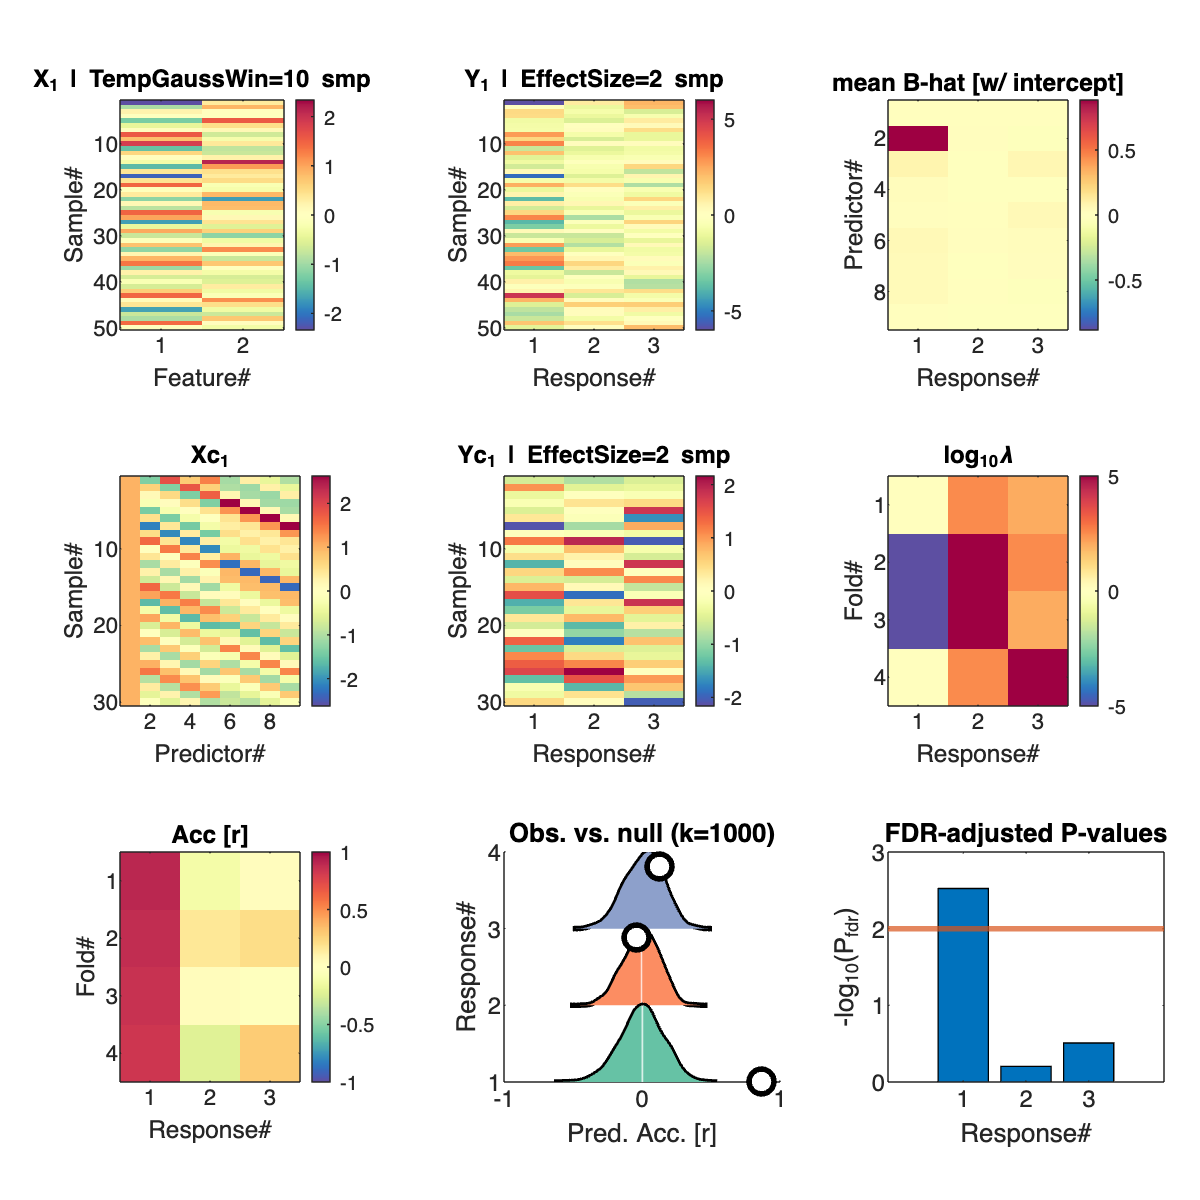

[plotmdl|2025-03-29_13:32:51] Figure saved: /tmp/tp607338ee_1023_41ad_b3e4_6206cd908de3/mdl_acc.pdf

[lea_test|2025-03-29_13:32:51] ALL PASSED!


TestJob = lea_test(struct(IsPlot=true, EffectSize=2, nRands=1000, TempGaussWin=10, DelaysSmp=(0:3), IsAssert=true, RelToiSec=[10 -10]));

Now, let me unpack some stuff from the figure:

**INPUT** *The first row, the first column*: the generated two features of the first (1) fold $\mathbf{X}_1$ are visualized as a matrix in color (Blue: negative values, Yellow: zero, Red: positive values). The parameter `Job.TempGaussWin` is noted, which controls the temporal smoothness of the features (the Gaussian smoothing window size in samples). The row represents time points in samples, the column represents each feature. *The first row, the second column*: the generated responses of three response units of the first (1) fold $\mathbf{Y}_1$ are shown. The parameter `Job.EffectSize` is noted, which controls the magnitude of the effect size in the toy example, which is always a zero-lag copy of the first feature to the first response prior to smoothing.

**CONFORMED DATA** *The second row, the first column*: the conformed design matrix of the first fold $\mathbf{X}_{c1}$ are visualized. Note that an intercept is added in the first column and that features are high-pass filtered, delayed per `Job.DelaysSmp`, and cropped per `Job.RelToiSec`. Here we call these columns as "predictors". *The second row, the second column*: the conformed responses of the first fold $\mathbf{Y}_{c1}$ are visualized.

**FITTING** *The first row, the third column*: CV-fold-averaged weight estimates in the dimension of the number of predictors and the number of responses. *The second row, the third column*: optimized ridge hyperparameter $\lambda$ is shown for each response (columns) and the CV-folds (the rows), colored in a base 10 log scale (here the bluish color means $\lambda<1$, which means the power of 10 with a negative exponent). *The third row, the first column*: prediction accuracies in Pearson correlation 

**INFERENCE** *The third row, the second column*: the ridgeline plot shows the null distributions of prediction accuracies for each response unit in different colors from the bottom to the top, averaged acrss CV folds. The number of null distributions is controlled by `Job.nRands`, and each null prediction was made after randomly rotating the phases of features and repeating the whole process without re-optimization (i.e., optimal lambdas were based on the real data). The white shades mark the 95% confidence interval of the mean of the generated null distributions. The white circles mark the observed prediction accuracies for each response, also averaged across CV folds. *The third row, the third column*: the bar plot shows P-values in a base 10 log scale, adjusted using false discovery rate (FDR). The one-tailed P-values (${\mathcal H}_0: r \le 0$) were calculated based on the generated null distribution. For reference, a red horizontal line is drawn at $P = 0.01$ (i.e., $-log_{10}P=2$).

## EXAMPLE #2: Real data

This is from th real-data analsis in the preprint (Kim, 2025, bioRxiv).